# Generate BPSK IQ Samples

This script creates a file with the IQ samples of a BPSK mapped message that we want to transmit.

#### Sampling parameters

The first step is to define the rate at which the signal is sampled in time (*fs* & *Ts*). This is critical for ensuring accurate digital signal processing.

fs = 1e6;  % Sampling frequency
Ts = 1/fs; % Sampling time

#### Generating the BPSK symbols

Once we have defined the frequency parameter, we can create a random binary sequence of length 112 using ***rand***. We use the the ***sign()*** function to map the binary data into +1 or -1 to represent the two possible BPSK symbols. Then, the ***complex()*** function ensures the symbols are stored as complex values with zero imaginary components.

txSymbols=complex(sign(rand(112,1)-0.5));

#### Convert symbols to samples

As next step, each BPSK symbol is upsampled to create "**samplesPerSymbol**" samples per symbol. And, we use the function ***rectpulse()*** to  perform rectangular pulse shaping, ensuring that each symbol is represented as a constant value over `8` consecutive samples.

samplesPerSymbol = 8; % Sample per symbol
txSamples = rectpulse(txSymbols, samplesPerSymbol); % Symbol to smaple conversion (pulse shaping)

Now, we can visualize the real part of the sampled signal to confirm the pulse shaping and upsampling are correct.

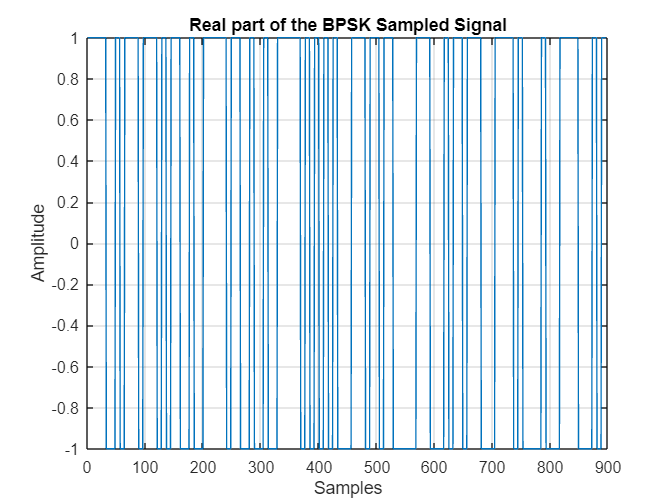

% Plot signal
figure
plot (real(txSamples))
grid on
xlabel("Samples")
ylabel("Amplitude")
title("Real part of the BPSK Sampled Signal")

#### Build burst signal

Lastly, we modify the signal so it's bursted. This is way it's easier to *visually* know when the frame starts and ends. 

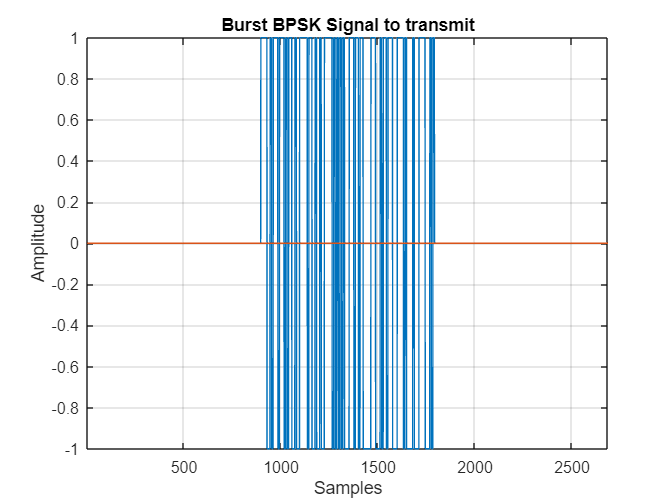

samplesPerFrame = numel(txSamples);   % Total number of samples
frameDuration   = samplesPerFrame*Ts; % Frame duration (Number of samples per frame * sampling time)

% Append zeros at the start and end to create bursted signal
burstedSignal   = [complex(zeros(samplesPerFrame,1));txSamples;complex(zeros(samplesPerFrame,1))]; 

% Plot bursted signal
figure
plot ([real(burstedSignal), imag(burstedSignal)])
title("Burst BPSK Signal to transmit")
xlabel("Samples")
ylabel("Amplitude")
axis tight;
grid on

As we can see in the graph above, we have appended zeros at the beginning and the end of the signal that we want to transmit. Appending zeros separates the signal into clear bursts, and this plot basically shows both the real and imaginary parts of the burst signal for validation.

#### Build and save IQ samples

Finally, we just need to convert the burst signal into a time series, using the function ***timeseries()*****. **Then, we add some metada that will be required for further processing or transmission. Basically, we are saving as metadata the sampling frequency, the frame duration, the specific modulation (BPSK), the samples per symbol, number of transmitted bits and some user data. Then, we save it for later use with the name **"BPSK_IQ_samples_simulation"**. This data, will be loaded in the following file "BPSK_Transmitter.mlx", since it contains the information that we want to transmit with the Pluto.

% Make IQ samples as a time series
IQSamples = timeseries(burstedSignal,"Name","IQSamples");

% Add userData
userData.fs                 = fs;
userData.signalDuration     = frameDuration; 
userData.modulation         = "BPSK";
userData.samplesPerSymbol   = samplesPerSymbol;
userData.numBits            = numel(txBits);
IQSamples.DataInfo.UserData = userData;

% Save IQ samples to file
%fileName = "BPSK_IQ_samples_simulation";
save(fileName,"IQSamples")